# Analyze heat capacity from DR

This routine is intended at analyzing Cp data acquired with our DR used in the Dynacool PPMS of the Lee lab

## To do: 

- Error bars:

-     For dT data, use standard deviation

-     For dCp values, add the SampHCErrmJmoleK field 

## Import data YTmVO4

Data = ImportCpDR('2018-07-31_TmVO4-LS5228-DR-HC180731.dat');
Data0 = importCpSharedPPMS_('20180322_TmVO4-LS5228-MP3-Plt-HC1803_Cp.dat');
Data10 = ImportCpDR('DRHC_10YTmVO4-LS5251-DR-HC180511.dat');
Data15 = ImportCpDR('DRHC_15Y-TmVO4-LS5343-DR-HC180721.dat');
Data18 = ImportCpDR('2018-07-24_DR-HC_18Y-TmVO4-LS5348-DR-HC180724.dat');
Data20 = ImportCpDR('DRHC_20YTmVO4-LS5252-DR-HC180519.dat');
Data22 = ImportCpDR('2018-07-23_DR-HC_22Y-TmVO4-LS5344-DR-HC180723.dat');
Data24 = ImportCpDR('2018-07-25_DR-HC_24Y-TmVO4-LS5349-DR-HC180725.dat');
Data30 = ImportCpDR('DRHC_30YTmVO4-LS5335-DR-HC180526.dat');

## Import data Tm(V,As)O4

AsData0=ImportCpFisherPPMSTable('TmAsO4-LS5341-HC180602_2018-06-02.dat');
AsData10 = importCpSharedPPMS_('2018-09-07_10V-TmAsO4-LS5350-HC180907_CpvsT.dat');

## Concatenate them in a cell array

split = {Data; Data10; Data15; Data18; Data20; Data22; Data24; Data30;AsData0;AsData10;AsData0};
LY = length(split)-3;
L = length(split);

## Rename variables

isTableCol = @(t, thisCol) ismember(thisCol, t.Properties.VariableNames);
% function to test if a column exists in a table
for i=1:L% for doped samples measured in DR
    if isTableCol(split{i},'SampleTempKelvin')
        split{i}.Properties.VariableNames{'SampleTempKelvin'} = 'T';% rename the temperature column
    end
    if isTableCol(split{i},'FieldOersted')
        split{i}.Properties.VariableNames{'FieldOersted'} = 'H';% rename the magnetic field column
    end
    if isTableCol(split{i},'SampHCJK')% for samples measured in DR
        split{i}.Properties.VariableNames{'SampHCJK'} = 'Cp';% rename the heat capacity column
    elseif isTableCol(split{i},'SampHCmJmoleK')% for samples measured in shared PPMS
        split{i}.Properties.VariableNames{'SampHCmJmoleK'} = 'Cp';
    elseif isTableCol(split{i},'SampHCJmoleK')% for samples measured in Fisher He4 PPMS
        split{i}.Properties.VariableNames{'SampHCmJmoleK'} = 'Cp';
    end
end

## Remove NaN rows

for i=1:L
    split{i}(any(isnan(split{i}.T), 2), :) = [];% Remove rows where T is NaN
end

## Keep only data under zero magnetic field

for i=1:L-1%for all data but the last dataset
    split{i} = split{i}(round(split{i}.H,-1)==0,:);% keep only data at zero field
end
split{L} = split{L}(round(split{L}.H,-1)==20000,:);% keep only data at 20000 Oe for the second TmAsO4 dataset

## Plot parameters for heat capacity

xlblTemp = 'Temperature (K)';
ylblCp = 'C_p (J\cdotmol^{-1}\cdotK^{-1})';
ttlCpY ='Heat capacity of Tm_{1-x}Y_xVO4';
ttlCpAs ='Heat capacity of TmAs_{1-x}V_xO4';

## Compute molar heat capacity

M = [283.87326% Molar mass of each sample, in g/mol
275.3902538
271.869006
269.4681552
266.3470492
266.2670208
264.6664536
258.6643266
307.8534
305.45539
307.8534];
m = 1e-3*[0.38% mass in g of the sample on which each dataset was measured
0.13
0.24
0.045
0.25
0.59
0.76
0.14
1.23
0.35%This value was adjusted (instead of 0.32mg) in order to let the
1.23];
% curve fall on top of that of the parent compound
dpg = 1e-2*[0% Y content for each dataset
10.6
15.3%
18.1%
21.9%
22.0%
24.8%
31.5
0% This is V content in Tm(As,V)O4
10.80
0];
% split{1}.Cpmol = split{1}.Cp *1e-3;% molar heat capacity, in J/mol/K,
% starting from a heat capacity in mJ/mol/K as is measured in the shared PPMS
for i=1:LY
    split{i}.Cpmol = split{i}.Cp *1e-6*M(i)/(m(i)*(1-dpg(i)));% molar heat capacity, in J/mol/K
    % starting from a heat capacity measured in microJoules per Kelvin, as is measured in the DR
    % Cpmol is calculated per mole of Tm3+ ions, hence the (1-dpg) factor in the denominator
end
for i=L-2:L
    split{i}.Cpmol = split{i}.Cp *1e-6*M(i)/m(i);% molar heat capacity, in J/mol/K
    % starting from a heat capacity measured in microJoules per Kelvin, as is measured in the DR
    % Cpmol is calculated per mole of Tm3+ ions, hence the (1-dpg) factor in the denominator
end

## Plot the dataset for YTmVO4

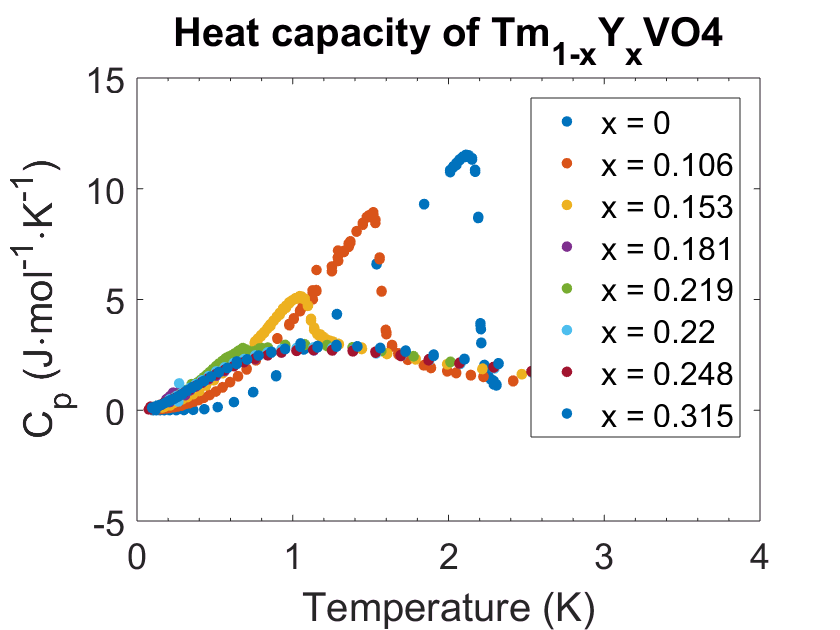

plotCpDoping(split,dpg,1,LY,ttlCpY)

## Plot the dataset for TmAsVO4

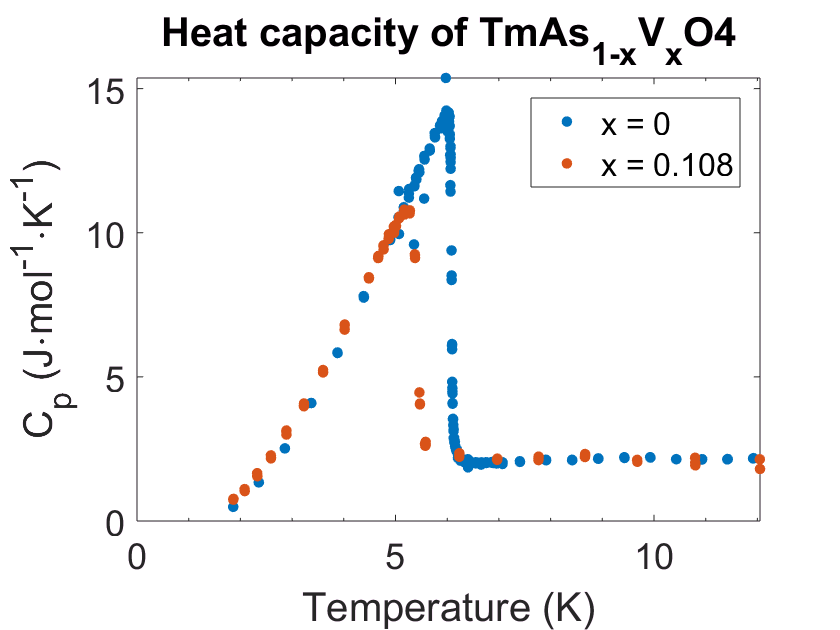

plotCpDoping(split,dpg,L-2,L-1,ttlCpAs)
xlim([0 inf]);ylim([0 inf]);

# Average data

## Sort each dataset by increasing value of temperature

for i=1:L
    srtd{i} = sortrows(split{i},{'T'});
%     [split{i}.T,wo] = sort(split{i}.T);
%     split{i}.Cp = split{i}.Cp(wo);
end
srtd = srtd';

## Test the temperature scattering between data points supposedly taken at the "same" temperature

4mK is the empirical maximal dispersion of data points taken consecutively at a given temperature. In order to check this, one can run the following code on the temperature variable T:

nrep = 3;% number of repetitions of the measurement at each temperature
% We want to compute the temperature separation between two data points
% that are NOT repetitions of the same measurement
Tsep = 4e-3;% value of temperature separation to be tested, in Kelvin
% Data points taken within an interval of Tsep are considered to be measured at the same temperature setpoint
for i = 1
    for k = 1:length(srtd{i}.T)-nrep
        if abs(srtd{i}.T(k+nrep)-srtd{i}.T(k))<Tsep
% if the values of temperature for two data points supposedly
% measured at two different temperature setpoints are separated by less than Tsep
            srtd{i}.T(k);% display the value of temperature for the first data point
        end
    end
end

IF this piece of code outputs one or more values AND IF these values obviously correspond to measurements that were supposed to be measured at different temperature setpoints, THEN reduce Tsep in order to reach a value for which the code does not output anything.

## Compute average of data points taken

for i = 1:L
    Tm = [];Cpm = [];stdCpm = [];% initialize temporary tables;
    k = 1;% initiliaze loop index k
    while k<length(srtd{i}.T)% loop over k
        ind = [k];% initialize temporary table of indices
        j = k+1;% initialize subloop index 
        while abs(srtd{i}.T(j)-srtd{i}.T(k))<Tsep
            % loop over datapoints within a temperature interval of Tsep
            % i.e. datapoints measured at the same temperature setpoint
            ind = [ind, j];% store index of current datapoint
            j = j+1;% increase subloop index
            if j>= length(srtd{i}.T)% safety condition
                break
            end
        end
        if length(ind)>1% do not include isolated data points
            Tm = [Tm,mean(srtd{i}.T(ind))];% average of temperature for data points
            % taken at the same temperature setpoint
            Cpm = [Cpm,mean(srtd{i}.Cpmol(ind))];% average of heat capacity
            stdCpm = [stdCpm,std(srtd{i}.Cpmol(ind))];% standard deviation of heat capacity
        end
        k = j+1;% once all datapoints measured at the same temperature setpoints are averaged,
        % increase the main loop index in order to jump to the next data point measured
        % at a different temperature setpoint
    end
    avgData(i).T = Tm;% store the full averaged temperature table
    avgData(i).Cp = Cpm;% store the full averaged heat capacity table
    avgData(i).stdCp = stdCpm;% store the full table of standard deviation of heat capacity
end

## Plot averaged Cp data for YTmVO4 x<xc

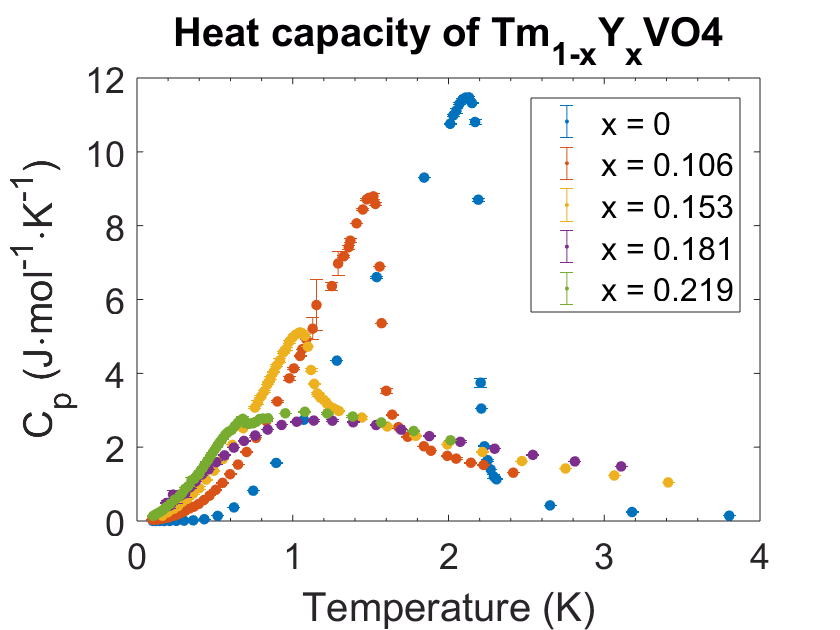

rcidx = 3;% reverse critical index = integer such that split{L-rcidx} is the last dataset with Cp jump
plotAvgCp(avgData,dpg,1,LY-rcidx)
title(ttlCpY)

## Plot averaged Cp data for YTmVO4 x=0,0.1

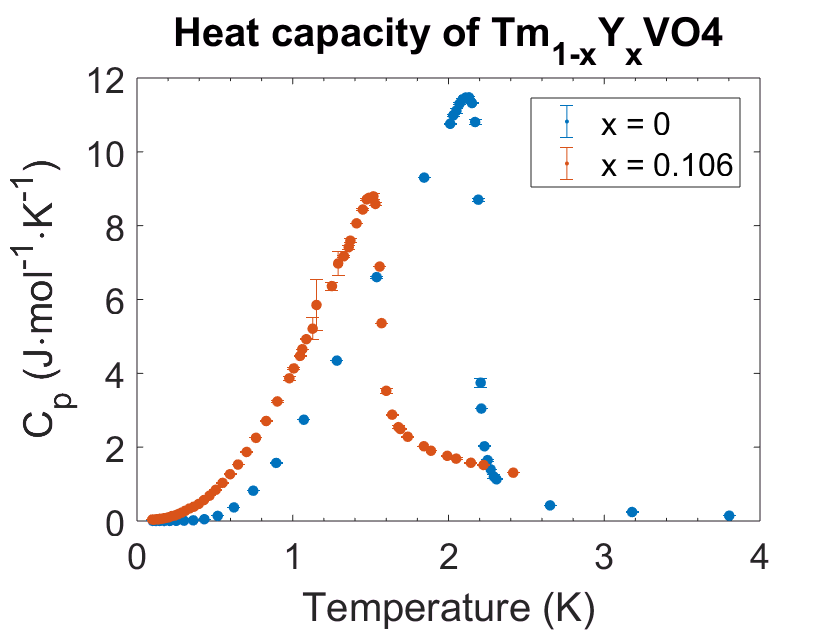

plotAvgCp(avgData,dpg,1,2)
title(ttlCpY)

## Plot averaged Cp data for TmAsVO4 x<xc

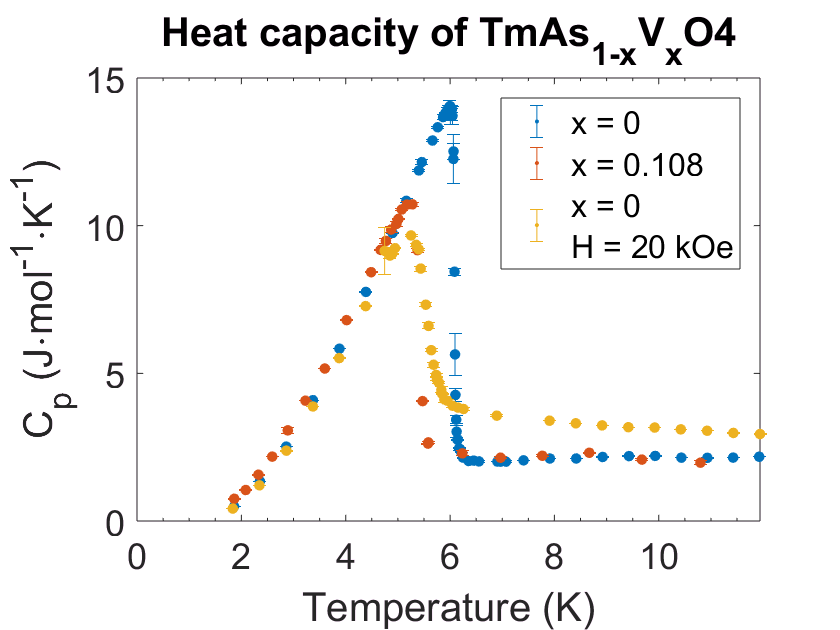

plotAvgCp(avgData,dpg,L-2,L-1)
errorbar(avgData(L).T,avgData(L).Cp,avgData(L).stdCp,'.','MarkerSize',18,'DisplayName',['x = 0',newline,'H = 20 kOe'])
title(ttlCpAs)
xlim([0 inf])

## Plot averaged Cp/T data for x<xc

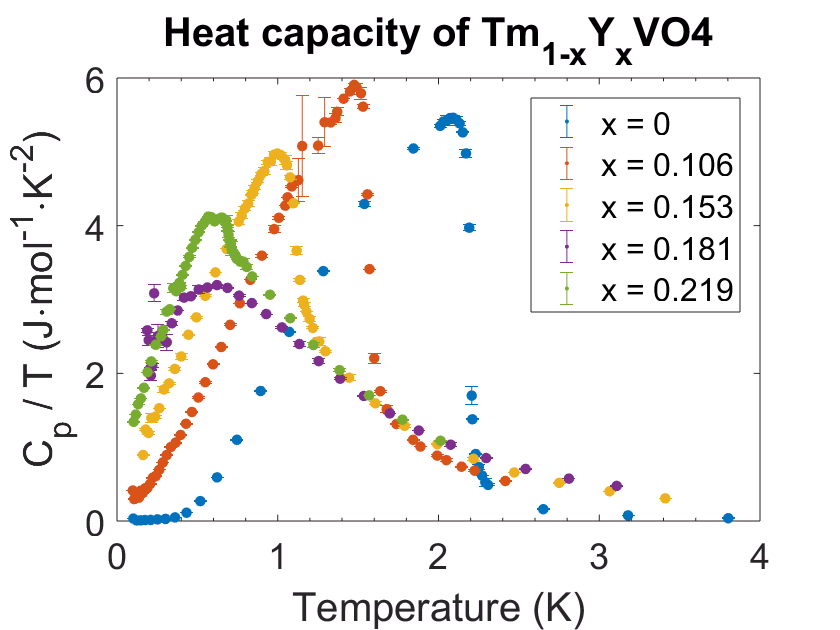

plotAvgCpoverT(avgData,dpg,1,LY-rcidx)
title(ttlCpY)

## Plot averaged data for x>xc

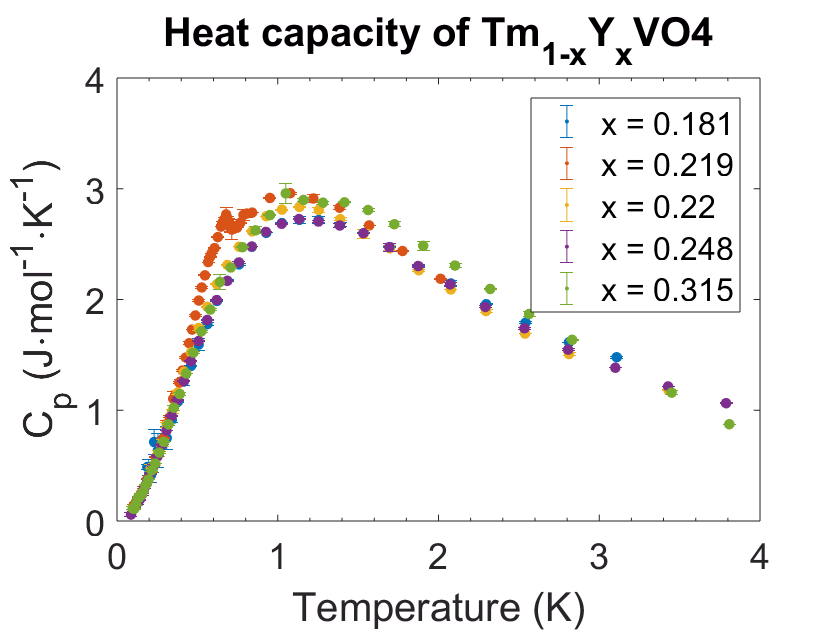

plotAvgCp(avgData,dpg,LY-rcidx-1,LY)
title(ttlCpY)

## Plot averaged Cp/T data for x>xc

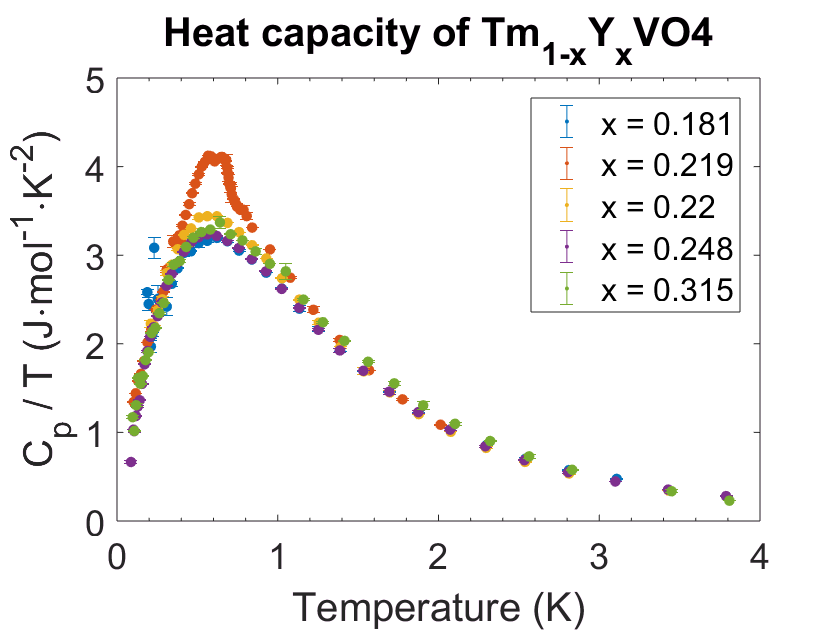

plotAvgCpoverT(avgData,dpg,LY-rcidx-1,LY)
title(ttlCpY)

# Temperature derivative of heat capacity

## Compute dCp/dT

ylbldCp = 'dC_p / dT (J\cdotmol^{-1}\cdotK^{-2})';
ttldCp = 'dC_p / dT of Tm_{1-x}Y_xVO4';
close;figure
for i=1:L
    avgData(i).dCp = diff(avgData(i).Cp)';% differential of Cp
    avgData(i).dT = diff(avgData(i).T');% differential of T
    avgData(i).Tm = mean([avgData(i).T(1:end-1);avgData(i).T(2:end)])';% in order ot have the same # of data points as in dCp
    avgData(i).derCp = avgData(i).dCp ./ avgData(i).dT;% temperature derivative of Cp
end

## Plot dCp/dT for YTmVO4 x<xc

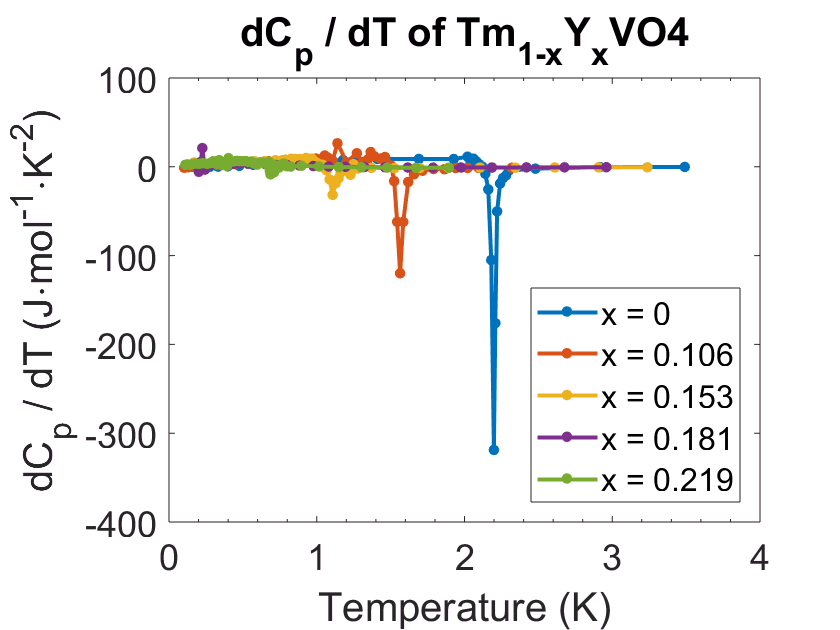

for i=1:LY-rcidx
    plot(avgData(i).Tm,avgData(i).derCp,'.-','MarkerSize',18,'DisplayName',['x = ',num2str(dpg(i))])
    hold on
end
xlabel(xlblTemp);ylabel(ylbldCp);title(ttldCp);legend('show','Location','southeast');

## Plot dCp/dT for YTmVO4 x>xc

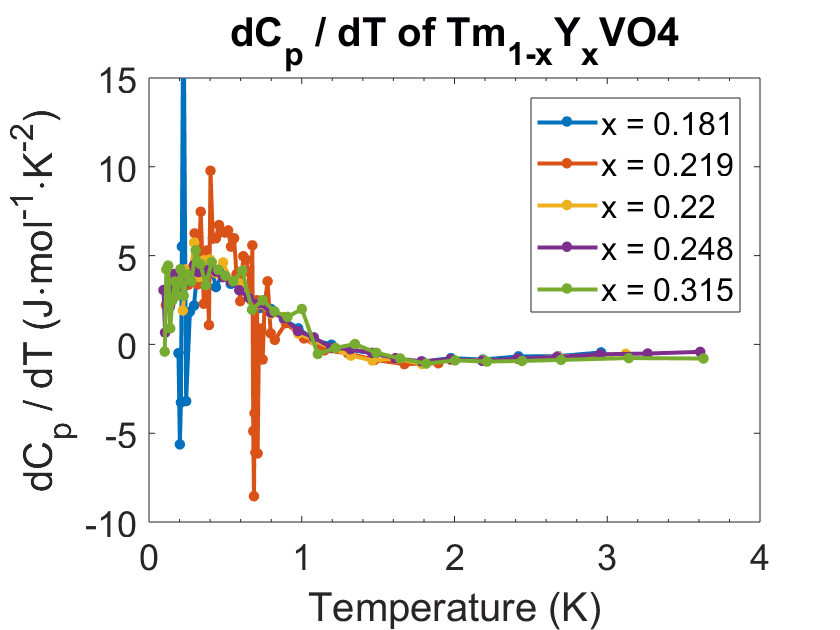

close;figure
for i=LY-rcidx-1:LY
    plot(avgData(i).Tm,avgData(i).derCp,'.-','MarkerSize',18,'DisplayName',['x = ',num2str(dpg(i))])
    hold on
end
xlabel(xlblTemp);ylabel(ylbldCp);title(ttldCp);legend('show')
ylim([-10 15])

## Plot dCp/dT for V-TmAsO4

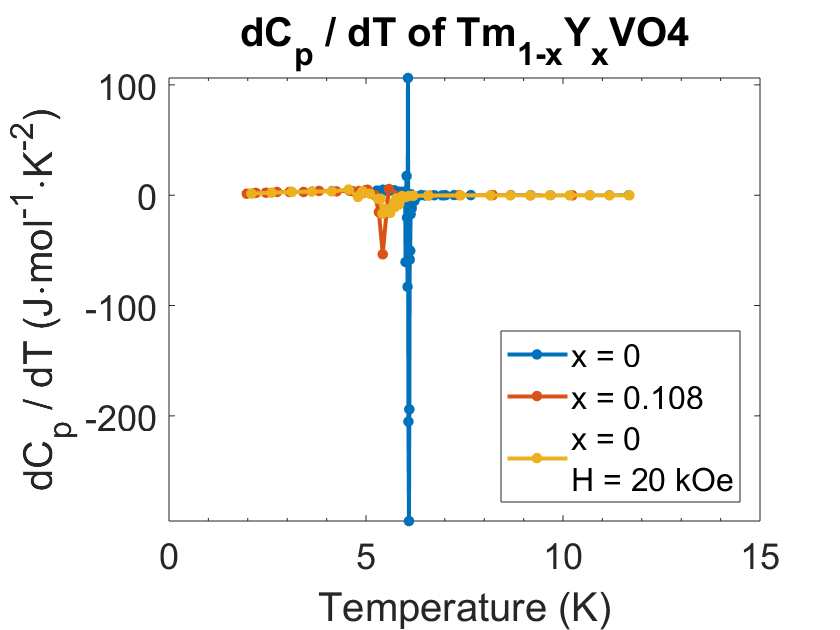

close; figure
for i=L-2:L-1
    plot(avgData(i).Tm,avgData(i).derCp,'.-','MarkerSize',18,'DisplayName',['x = ',num2str(dpg(i))])
    hold on
end
plot(avgData(L).Tm,avgData(L).derCp,'.-','MarkerSize',18,'DisplayName',Asfldlgd(dpg,L,srtd))
xlabel(xlblTemp);ylabel(ylbldCp);title(ttldCp);legend('show','Location','southeast');
ylim([-inf inf])

# Determine jump of Cp at transition

## Need to document this section

for i=1:L
    if min(avgData(i).derCp)>-5
        disp(' ')
        continue
    end
    idxMaxderCp = find(avgData(i).derCp==min(avgData(i).derCp))
    avgData(i).Tc = avgData(i).Tm(avgData(i).derCp==min(avgData(i).derCp));
    j = idxMaxderCp;
    while any(avgData(i).derCp(j:j+2)<-5)
    % if the current data point or any of the two following data points still have a significantly decreasing slope
    % this is useful for datasets where the jump is small
        j = j+1;
        if j>length(avgData(i).derCp)
            break
        end
    end
    idxjumpstart = j
    if idxjumpstart-idxMaxderCp<=1
        disp(' ')
        continue
    end
    Tderstart = avgData(i).Tm(idxjumpstart);
    avgData(i).Tjumpend = avgData(i).T(avgData(i).Cp==max(avgData(i).Cp(avgData(i).T<Tderstart)));
    disp(['Tjumpend = ',num2str(avgData(i).Tjumpend)])
    if avgData(i).Tjumpend>Tderstart
        continue
    end
    Tjump = avgData(i).T((avgData(i).T>=avgData(i).Tjumpend)&(avgData(i).T<Tderstart));
    avgData(i).Tjumpstart = max(Tjump);
    disp(['Tjumpstart = ',num2str(avgData(i).Tjumpstart)])
    avgData(i).deltaCp = avgData(i).Cp((avgData(i).T==avgData(i).Tjumpend)) - avgData(i).Cp((avgData(i).T==avgData(i).Tjumpstart));
    disp(['deltaCp = ',num2str(avgData(i).deltaCp)])
    avgData(i).dTcplus = avgData(i).Tjumpstart - avgData(i).Tc;% width of the transition on the right
    avgData(i).dTcminus = avgData(i).Tc - avgData(i).Tjumpend;% width of the transition on the right
    disp(' ')
end

idxMaxderCp = 27

idxjumpstart = 33

Tjumpend = 2.1311


Tjumpstart = 2.2914


deltaCp = 10.276


idxMaxderCp = 47

idxjumpstart = 51

Tjumpend = 1.5178


Tjumpstart = 1.6782


deltaCp = 6.2492


idxMaxderCp = 35

idxjumpstart = 43

Tjumpend = 1.0456


Tjumpstart = 1.2387


deltaCp = 2.1066


idxMaxderCp = 2

idxjumpstart = 3

idxMaxderCp = 35

idxjumpstart = 41

Tjumpend = 0.67904


Tjumpstart = 0.71372


deltaCp = 0.13672


idxMaxderCp = 25

idxjumpstart = 35

Tjumpend = 6.001


Tjumpstart = 6.2481


deltaCp = 11.9081


idxMaxderCp = 18

idxjumpstart = 20

Tjumpend = 5.2762


Tjumpstart = 5.5767


deltaCp = 8.1015


idxMaxderCp = 13

idxjumpstart = 23

Tjumpend = 5.2522


Tjumpstart = 5.8486


deltaCp = 5.3659


## Plot the jump of Cp vs doping

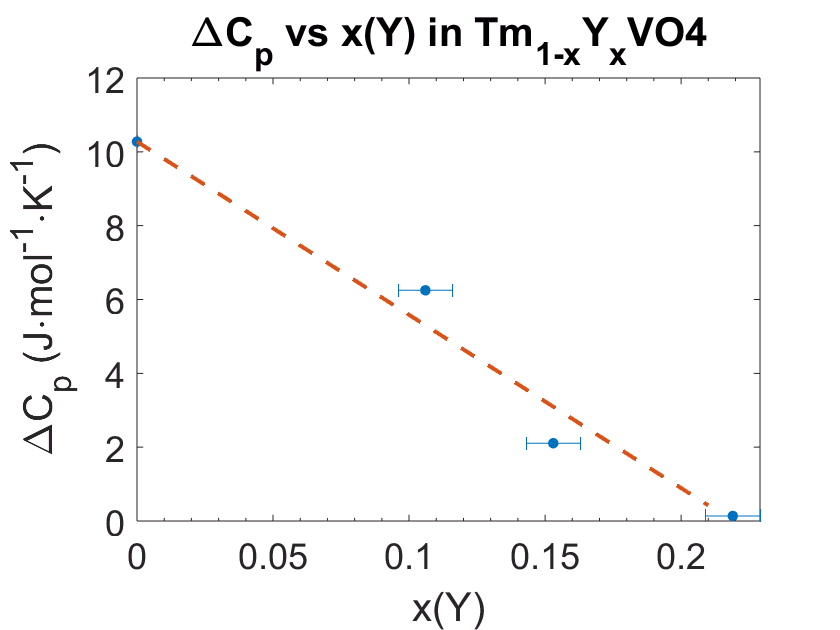

% First extract the relevant values of doping
deltaCp = [avgData.deltaCp];% array containing all non-empty values of avgData.deltaCp
Ldelta = length(deltaCp);%
idxdeltaCp = false(Ldelta,1);
dpgjump = ones(Ldelta,1);
for ii=1:L
    jj = ii;
    if avgData(jj).deltaCp
        idxdeltaCp(ii)=true;
        jj = jj+1;
    else jj = jj+1;
    end
end
dpgjump=dpg(idxdeltaCp);
dpgjumperr = 0.01*ones(length(deltaCp),1);dpgjumperr(1) = 0;

% Linear guide to the eye
xgmax = max(dpgjump);
xguide = 0:0.01:xgmax;
yguidex = deltaCp(1)*(1-xguide/xgmax);

% Actual plot
LdeltaY = 4;% number of elements of deltaCp that relate to YTmVO4; determined visually/manually
ylbldeltaCp = '\DeltaC_p (J\cdotmol^{-1}\cdotK^{-1})';
ttldeltaCp = '\DeltaC_p vs x(Y) in Tm_{1-x}Y_xVO4';
figure
errorbar(dpgjump(1:LdeltaY),deltaCp(1:LdeltaY),dpgjumperr(1:LdeltaY),'horizontal','.','MarkerSize',18)
hold on
plot(xguide,yguidex,'--')
xlabel('x(Y)');ylabel(ylbldeltaCp);title(ttldeltaCp);%legend('show');
xlim([0 inf])

## Plot deltaCp vs T_Q

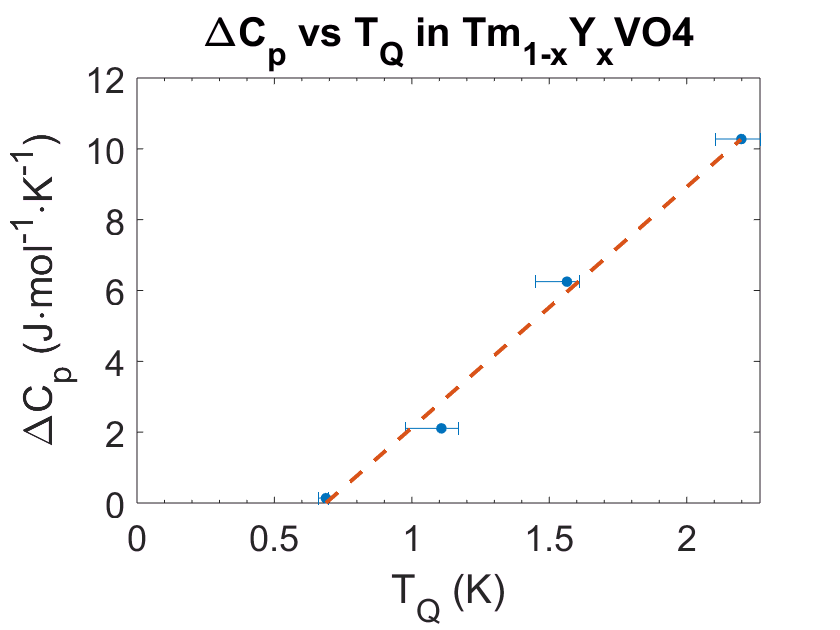

% Compute values of T_Q matching the non-zero values of deltaCp
Tc = [avgData.Tc];dTcp = [avgData.dTcplus];dTcm = [avgData.dTcminus];
Tc(4) = [];% there is no measurable jump in Cp at x = 0.18

% Linear guide to the eye
tgmax = max(Tc(1:LdeltaY));tgmin = min(Tc(1:LdeltaY));
tguide = tgmin:0.01:tgmax;
yguidet = deltaCp(1)*(tguide-tgmin)/(tgmax-tgmin);

% Actual plot
ttldeltaCpvsTc = '\DeltaC_p vs T_Q in Tm_{1-x}Y_xVO4';
figure
errorbar(Tc(1:LdeltaY),deltaCp(1:LdeltaY),dTcp(1:LdeltaY),dTcm(1:LdeltaY),'horizontal','.','MarkerSize',18)
hold on
plot(tguide,yguidet,'--')
xlabel('T_Q (K)');ylabel(ylbldeltaCp);title(ttldeltaCpvsTc);%legend('show');
xlim([0 inf])

## Plot deltaCp vs 1 - T_Q / T_Q(0)

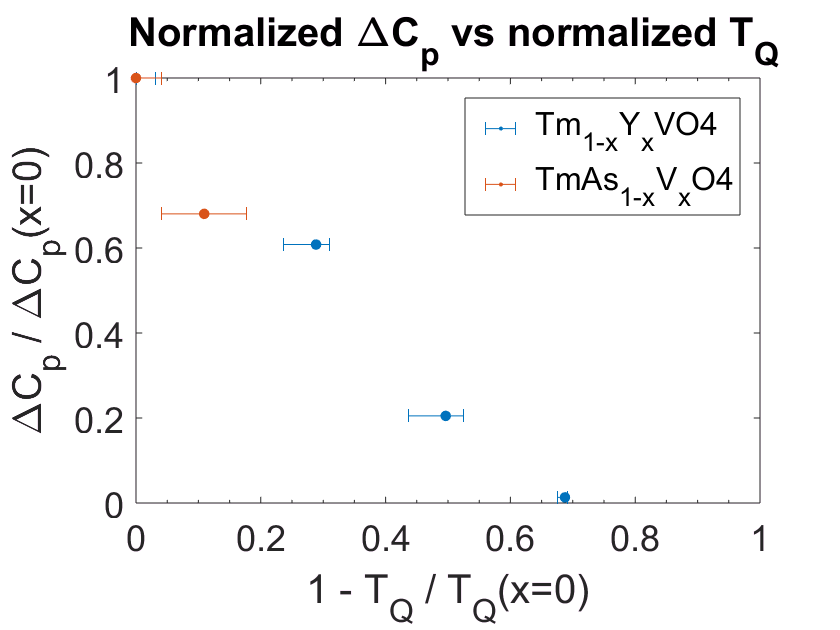

dTcp(1) = 0;
figure
errorbar(1-Tc(1:LdeltaY)/Tc(1),deltaCp(1:LdeltaY)/deltaCp(1),dTcp(1:LdeltaY)/Tc(1),dTcm(1:LdeltaY)/Tc(1),'horizontal','.','MarkerSize',18,'DisplayName','Tm_{1-x}Y_xVO4')
hold on 
errorbar(1-Tc(LdeltaY+1:Ldelta-1)/Tc(LdeltaY+1),deltaCp(LdeltaY+1:Ldelta-1)/deltaCp(LdeltaY+1),dTcp(LdeltaY+1:Ldelta-1)/Tc(1),dTcm(LdeltaY+1:Ldelta-1)/Tc(1),'horizontal','.','MarkerSize',18,'DisplayName','TmAs_{1-x}V_xO4')
xlabel('1 - T_Q / T_Q(x=0)');ylabel('\DeltaC_p / \DeltaC_p(x=0)');
title(' Normalized \DeltaC_p vs normalized T_Q');
legend('show');
xlim([0 1])

## Plot deltaCp / T_Q vs T_Q

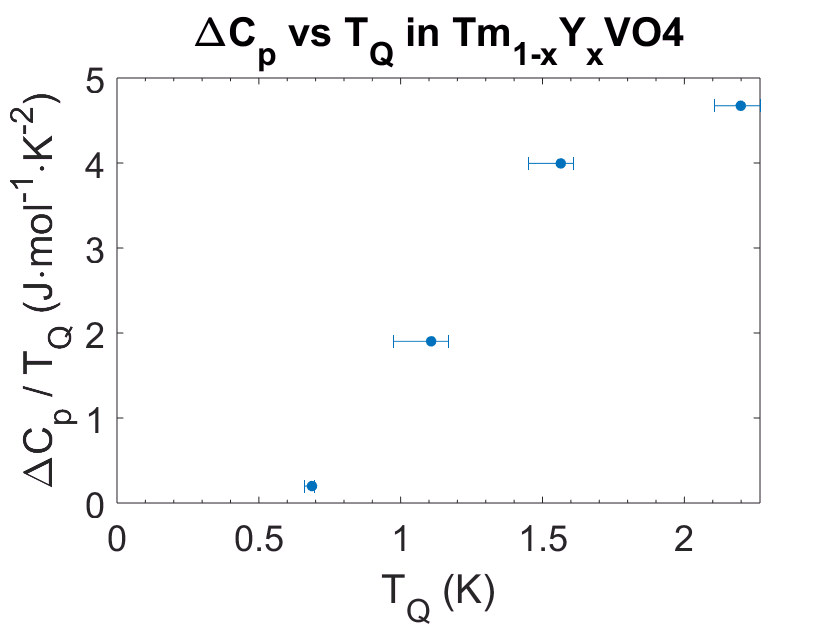

ylbldeltaCpoverTc = '\DeltaC_p / T_Q (J\cdotmol^{-1}\cdotK^{-2})';
figure
errorbar(Tc,deltaCp./Tc,dTcp,dTcm,'horizontal','.','MarkerSize',18)
xlabel('T_Q (K)');ylabel(ylbldeltaCpoverTc);title(ttldeltaCpvsTc);%legend('show');
xlim([0 inf])

## Function for plot legend of TmAsO4 under field

function strlgd = Asfldlgd(dpglvl,n,mycellarray)%function name is short for "TmAsO4 field legend"
    strlgd = ['x = ',num2str(dpglvl(n)),newline,'H = ',num2str(round(mycellarray{n}.H(1)/1e3)),' kOe'];
end